# Expand Example 2.19:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the RLC circuit shown below:

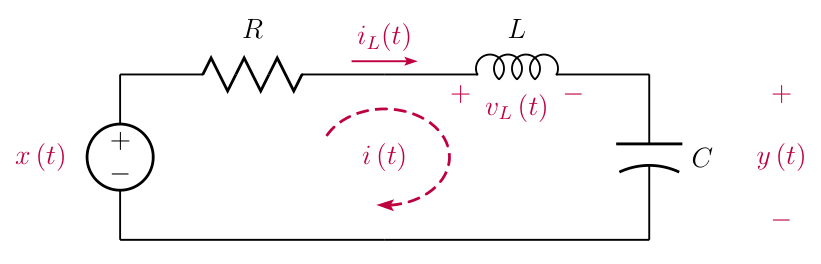

The governing differential equation is (see Example 2.6 in the text)


$$  \frac{d^{2}y\left(t\right)}{dt^{2}}+
  \frac{R}{L}\,\frac{dy\left(t\right)}{dt} +
  \frac{1}{LC}\,y\left(t\right) =
  \frac{1}{LC}\,x\left(t\right)$$


In this script we will compute the unit step response and the impulse response of this system through approximate numerical solution of the differential equation using the function ode45(...).  The function ode45(...) requires rewriting the differential equation in the form


$$\mathbf{\dot{w}}(t) = g\left(\mathbf{w}(t),t\right)$$


where $\mathbf{w}$ is a vector of two elements


$$\mathbf{w}(t)=
\left[\begin{array}{c}
w_{1}(t) \\
w_{2}(t)
\end{array}\right]$$


and $g(...)$ is a function.  We will assume the system is initially relaxed.  Let $w_{1}=y(t)$ and $w_{2}=dy(t)/dt$.  Then


$$\begin{array}{r l}
\frac{dw_{1}(t)}{dt}&=w_{2}(t) \\
\frac{dw_{2}(t)}{dt}&=-\frac{1}{LC}\,w_{1}(t)-\frac{R}{L}\,w_{2}(t)+\frac{1}{LC}\,x(t)
\end{array}$$


R = 2; % Resistance
L = 1; % Inductance
C = 0.04; % Capacitance

Compute and graph the output signal $y(t)$ in the time interval $-1\le t\le 5$ s.  Recall that $y(t)=w_{1}(t)$.

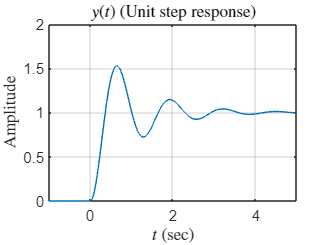

t = [-1:0.01:5];
[t,w] = ode45(@(t,w) RLCwithUnitStepInput(t,w,R,L,C), t, [0;0]);
y = w(:,1);
plot(t,y); grid;
axis([-1,5,0,2]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$y(t)$  (Unit step response)');

Impulse response can be found as the time derivative of the unit step response.  In our case that would be $w_{2}(t)$ which we already have.

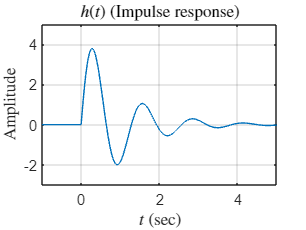

h = w(:,2);
plot(t,h); grid;
axis([-1,5,-3,5]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$h(t)$  (Impulse response)');

set(0,'defaultTextInterpreter','tex');

function wdot = RLCwithUnitStepInput(t,w,R,L,C)
  wdot = [0,1;-1/(L*C),-R/L]*w+[0;1]*1/(L*C).*(t>=0);
end